Add noise to the MRI image

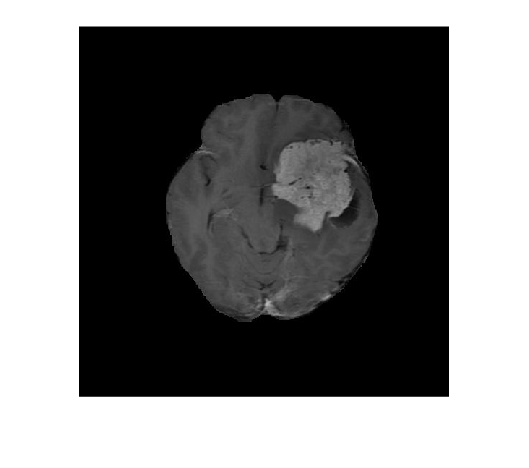

or = imread('..\brain\data\12 Anh Tach Hop So\U Mang Nao (Meningioma Tumor)\Tumor3_Skull_Tripped.jpg');
figure;
imshow(or);

noise_img = uint8(imnoiseFB(or,'gaussian',0.02));

Noises added here is Rican, which is the magnitude of the real and complex value of the Gaussian noise

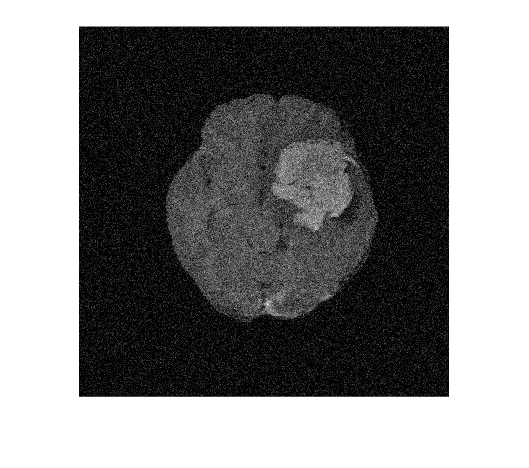

figure;
imshow(noise_img);

[psnr1, snr1] = psnr(noise_img, or);
psnr1

psnr1 = 21.1240

Decompose the noisy image using forward discrete HAAR wavelet transform

Level of decomposition selected is L=4

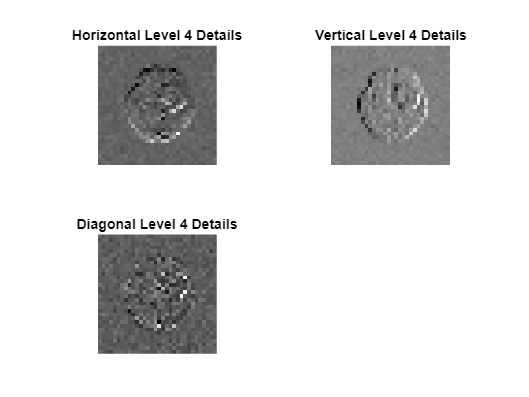

wmethod = 'haar';
[C,S]=wavedec2(noise_img,4,wmethod);
[H4,V4,D4] = detcoef2('all',C,S,4);
%[a,h,v,d] = haart2(noise_img,4);
figure;
subplot(2,2,1)
imshow(mat2gray(H4))
title('Horizontal Level 4 Details')
subplot(2,2,2)
imshow(mat2gray(V4))
title('Vertical Level 4 Details')
subplot(2,2,3)
imshow(mat2gray(D4))
title('Diagonal Level 4 Details')

Threshold the horizontal, vertical and diagonal coefficients using soft thresholding, hard thresholding and bayes shrink separately. 

Ch_s = wthcoef2('h',C,S,[2,3,4],[0.5,1,0.9],'s');
Cv_s = wthcoef2('v',Ch_s,S,[2,3,4],[0.5,1,0.9],'s');
Cd_d = wthcoef2('d',Cv_s,S,[2,3,4],[0.5,1,0.9],'s');

Ch_h = wthcoef2('h',C,S,[2,3,4],[0.5,1,0.9],'h');
Cv_h = wthcoef2('v',Ch_h,S,[2,3,4],[0.5,1,0.9],'h');
Cd_h = wthcoef2('d',Cv_h,S,[2,3,4],[0.5,1,0.9],'h');

aci = S(1,1)*S(1,2); % approximation index
% Baye_coff = C;
Baye_coff = [C(1:aci-1),zeros(1,length(aci:1:length(C)))];
% Function to estimate noise standard deviation
estimate_sigma = @(C) median(abs(C(:))) / 0.6745;

% Function to apply BayesShrink thresholding
bayes_shrink = @(C, sigma_est) sigma_est / sqrt(max(var(C(:)) - sigma_est, 0));
% Apply BayesShrink thresholding to detail coefficients at each level
max_level  = length(S)-2;
for level = 1:max_level
    [H, V, D] = detcoef2('all', C, S, level);
    sigma_est = estimate_sigma(D);
    H_thresh = bayes_shrink(H, sigma_est);
    V_thresh = bayes_shrink(V, sigma_est);
    D_thresh = bayes_shrink(D, sigma_est);

     % Apply soft thresholding
    H = wthresh(H,'s',H_thresh);
    V = wthresh(V,'s',V_thresh);
    D = wthresh(D,'s',D_thresh);
    Baye_coff = replace_detail_coeffs(Baye_coff,S,H,V,D,level);
end

Reconstruct the image using inverse discrete HAAR wavelet transform applying level 4 reconstruction.

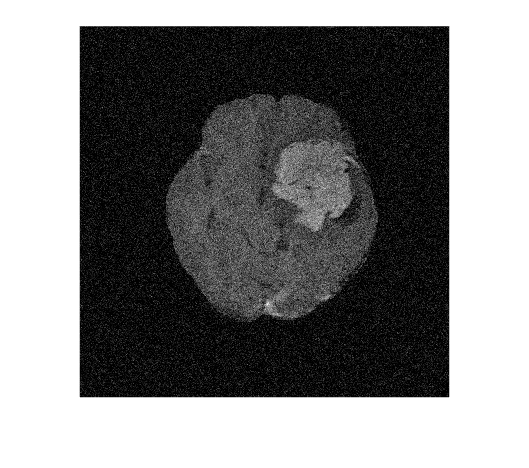

haar_img = uint8(waverec2(Baye_coff,S,wmethod));
figure;
imshow(mat2gray(haar_img))

[psnr2, snr2] = psnr(haar_img, or);
psnr2

psnr2 = 21.3527

Decompose the noisy image using forward discrete DB3 wavelet transform.

Level of decomposition selected is L=4

Threshold the horizontal, vertical and diagonal coefficients using soft thresholding, hard thresholding and bayes shrink separately. 

Reconstruct the image using inverse discrete DB3 wavelet transform applying level 4 reconstruction.

Fuse the two restored images obtained using HAAR and DB3 wavelets using simple average method

function output = getThresh(x,type)
    [thr,sorh,keepapp] = ddencmp('den','wp',x);
    output = wthresh(x,type,thr);
end

function new_coeffs = replace_detail_coeffs(coeffs, S, H, V, D, level)
    % Get the index ranges for the detail coefficients at the specified level
    pow2 = prod(S(1:end-level, :), 2);
    start_idx = pow2(1)+sum(pow2(2:end-1))*3 + 1;
    H_idx = start_idx : start_idx + pow2(end) - 1;
    start_idx = H_idx(end) + 1;
    V_idx = start_idx : start_idx + pow2(end) - 1;
    start_idx = V_idx(end) + 1;
    D_idx = start_idx : start_idx + pow2(end) - 1;
    
    % Replace the coefficients in the original array
    new_coeffs = coeffs;
    new_coeffs(H_idx) = H(:);
    new_coeffs(V_idx) = V(:);
    new_coeffs(D_idx) = D(:);
end